% USE data provided in 2015 paper
clear all
close all

cd '/home/hong/research/Master/Garch_graph/Molene_data'
path_data = '/home/hong/research/Master/Garch_graph/Molene_data';
dataset_name = 'temp_37'

dataset_name = 'temp_37'


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Loading and pre-processing

%% load data, and transfer to the centi degree
data = load(fullfile(path_data,strcat(dataset_name,'.mat')))
X = data.name(:,:) - 273.15
%X = data.name(:,:)
N = size(X,1)
T = size(X,2)
nodeinfo_name = 'node_37'
NodeInfo = load(fullfile(path_data,strcat(nodeinfo_name,'.mat')))
Xin_node = NodeInfo.name(:,:)

%%%% delete 13，15，26，28
H_arch = zeros(37,1);
h_adf  = zeros(37,1);
res_data = zeros(N,T);
for i = 1:N
    Mdl = arima(3,0,0);
    EstMdl = estimate(Mdl,X(i,1:744)');
    [res,~,logL] = infer(EstMdl,X(i,1:744)');
    H_arch(i,1) = archtest(res);
    h_adf(i,1) = adftest(X(i,1:744)');
    res_data(i,:) = res'
end

C1 = cov(res_data')
R1 = corrcoef(res_data')
imagesc(R1);
colorbar

C2 = cov(X')
R2 = corrcoef(X')
imagesc(R2);
colorbar


%% 123,56789101112,14
Xnew(1:3,:) = X(1:3,:)
Xnew(4:11,:) = X(5:12,:)
Xnew(12,:) = X(14,:)
Xin_new(1:3,:) = Xin_node(1:3,:)
Xin_new(4:11,:) = Xin_node(5:12,:)
Xin_new(12,:) = Xin_node(14,:)

% Xnew(1:3,:) = X(1:3,:)
% Xnew(4:11,:) = X(5:12,:)
% Xnew(12,:) = X(14,:)
% Xnew(13,:) = X(17,:)
% Xnew(14:16,:) = X(19:21,:)
% Xnew(17,:) = X(23,:)
% Xnew(18,:) = X(25,:)
% Xnew(19,:) = X(27,:)
% Xnew(20:27,:) = X(29:36,:)
% Xin_new(1:3,:) = Xin_node(1:3,:)
% Xin_new(4:11,:) = Xin_node(5:12,:)
% Xin_new(12,:) = Xin_node(14,:)
% Xin_new(13,:) = Xin_node(17,:)
% Xin_new(14:16,:) = Xin_node(19:21,:)
% Xin_new(17,:) = Xin_node(23,:)
% Xin_new(18,:) = Xin_node(25,:)
% Xin_new(19,:) = Xin_node(27,:)
% Xin_new(20:27,:) = Xin_node(29:36,:)

Xin_node_new(1:2,:) = Xin_new(1:2,:)
Xin_node_new(3:11,:) = Xin_new(4:12,:)

param = struct
param.k = 4
G = gsp_nn_graph(Xin_node_new,param)
G = gsp_adj2vec(gsp_compute_fourier_basis(G));
figure
G = gsp_compute_fourier_basis(G);
gsp_plot_graph(G)
view([0,90])



% C3 = cov(Xnew')
% R3 = corrcoef(Xnew')
% imagesc(R3);
% colorbar
% L_new = inv(C3)
% %[V1,D1]=eig(L_new);

%% Get the graph from node information
param = struct
param.k = 4
G = gsp_nn_graph(Xin_new,param)
G = gsp_adj2vec(gsp_compute_fourier_basis(G));
figure
G = gsp_compute_fourier_basis(G);
gsp_plot_graph(G)
view([0,90])

W_g = double(full(G.W))
L_g = double(full(G.L))

[V,D]=eig(L_g);
V_t = transpose(V);
Xhat = V_t * Xnew

X = Xnew
N=size(X,1)

%%%%%%%% test the res uncorrelated 
res_whole1 = zeros(N,T)
for i = 1:N
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,Xhat(i,1:T)');
    [res_whole1(i,:),~,logL] = infer(EstMdl,Xhat(i,1:T)');

end
C1 = cov(res_whole1')
R1 = corrcoef(res_whole1')
imagesc(R1);
colorbar

%%%%%%%% test the original res correlated 
res_whole = zeros(N,T)
for i = 1:N
    Mdl = arima('ARLags',[1,2,3,4],'MALags',[1,2,3,4],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,X(i,1:T)');
    [res_whole(i,:),~,logL] = infer(EstMdl,X(i,1:T)');

end

C = cov(res_whole')
R = corrcoef(res_whole') 
imagesc(R);
colorbar

% select the parameter in the origin domain
AR_Order = 5;
length = T;
sample_rate = 0.5;
p_val = 0.7;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record = zeros(AR_Order,N,3);
record_sum   = zeros(AR_Order,3);
iter = 0;
small_matrix = ones(1,val_L);

for AR = 1:AR_Order
    pre_val = zeros(N,val_L);
    error_val   = zeros(N,val_L);
    for i = 1:N
            X_train = X(i,1:index_train)';
            Mdl = arima(AR,0,0);
            EstMdl = estimate(Mdl,X_train);
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',X(i,1:index_train-1+index)');
            end
            iter = iter + 1
        
    end
    
    error_val = abs(pre_val - X(:,index_train+1:index_in));
    error_record(AR,:,1) = sum(error_val,2)/val_L;
    error_record(AR,:,2) = sum(error_val./(X(:,index_train+1:index_in) + small_matrix),2)/(val_L);
    error_record(AR,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum(AR,1) = sum(error_record(AR,:,1))/N;
    record_sum(AR,2) = sum(error_record(AR,:,2))/N;
    record_sum(AR,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));
end

[m,index_o]= min(record_sum(:,3))
AR_o = index_o

%%%% select the best parameter in frequency domain
AR_Order = 5;
length = T;
sample_rate = 0.5;
p_val = 0.7;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record1 = zeros(AR_Order,N,3);
record_sum1   = zeros(AR_Order,3);
iter = 0;
small_matrix = ones(1,val_L);

for AR = 1:AR_Order
    pre_val = zeros(N,val_L);
    error_val   = zeros(N,val_L);
    for i = 1:N
            X_train = Xhat(i,1:index_train)';
            Mdl = arima(AR,0,0);
            EstMdl = estimate(Mdl,X_train);
            
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',Xhat(i,1:index_train-1+index)');
            end
            iter = iter + 1
        
    end
    pre = V*pre_val
    error_val = abs(pre - X(:,index_train+1:index_in));
    error_record1(AR,:,1) = sum(error_val,2)/val_L;
    error_record1(AR,:,2) = sum(error_val./(X(:,index_train+1:index_in) + small_matrix),2)/(val_L);
    error_record1(AR,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum1(AR,1) = sum(error_record1(AR,:,1))/N;
    record_sum1(AR,2) = sum(error_record1(AR,:,2))/N;
    record_sum1(AR,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));
end

[m1,index_f]= min(record_sum1(:,3))
AR_f = index_f

% select the GARCH parameters in orinal domain
P_order = 1;
length = T;
sample_rate = 0.5;
p_val = 0.7;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record2 = zeros(2,N,3);
record_sum2   = zeros(2,3);
iter = 0;
small_matrix = ones(1,val_L);

for p = 0:1:P_order
    pre_val = zeros(N,val_L);
    error_val   = zeros(N,val_L);
    for i = 1:N
            X_train = X(i,1:index_train)';
            Mdl = arima('ARLags',[1,2,3],'Variance',garch(p,1));
            EstMdl = estimate(Mdl,X_train);
            
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',X(i,1:index_train-1+index)');
            end
            iter = iter + 1
        
    end
    pos = 1+p
    error_val = abs(pre_val - X(:,index_train+1:index_in));
    error_record2(pos,:,1) = sum(error_val,2)/val_L;
    error_record2(pos,:,2) = sum(error_val./(X(:,index_train+1:index_in) + small_matrix),2)/(val_L);
    error_record2(pos,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum2(pos,1) = sum(error_record2(pos,:,1))/N;
    record_sum2(pos,2) = sum(error_record2(pos,:,2))/N;
    record_sum2(pos,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));
end

[m2,index_o_g]= min(record_sum2(:,3))
p_o = index_o_g - 1

%select the GARCH parameters in frequency domain
P_order = 1;
length = T;
sample_rate = 0.5;
p_val = 0.7;
index_in = ceil(length* sample_rate);
index_train = ceil(index_in * p_val);
val_L = index_in-index_train;
error_record3 = zeros(2,N,3);
record_sum3   = zeros(2,3);
iter = 0;
small_matrix = ones(1,val_L);

for p = 0:1:P_order
    pre_val = zeros(N,val_L);
    error_val   = zeros(N,val_L);
    for i = 1:N
            X_train = Xhat(i,1:index_train)';
            Mdl = arima('ARLags',[1,2],'Variance',garch(p,1));
            EstMdl = estimate(Mdl,X_train);
            
            for index=1:val_L
                pre_val(i,index) = forecast(EstMdl,1,'Y0',Xhat(i,1:index_train-1+index)');
            end
            iter = iter + 1
        
    end
    pos = 1+p
    pre = V*pre_val
    error_val = abs(pre - X(:,index_train+1:index_in));
    error_record3(pos,:,1) = sum(error_val,2)/val_L;
    error_record3(pos,:,2) = sum(error_val./(X(:,index_train+1:index_in) + small_matrix),2)/(val_L);
    error_record3(pos,:,3) = sqrt(sum(error_val.^2,2)./sum(X(:,index_train+1:index_in).^2,2));
    record_sum3(pos,1) = sum(error_record3(pos,:,1))/N;
    record_sum3(pos,2) = sum(error_record3(pos,:,2))/N;
    record_sum3(pos,3) = sqrt(sum(sum(error_val.^2,2))/sum(sum(X(:,index_train+1:index_in).^2,2)));
end

[m3,index_f_g]= min(record_sum2(:,3))
p_f = index_f_g - 1

%%%%%%%%%% do the prediction BEST with garch(1,1) for both
AR_X = AR_o

函数或变量 'AR_o' 无法识别。

AR_Xhat = AR_f
MA_Order = 0
T = size(X,2)
length = size(X,2)
sample_rate = 0.5
p_val = 0.7
index_in = ceil(length* sample_rate)
index_train = ceil(index_in * p_val)
test_L = length  - index_in
H = 12

H = 12

%%%% var_f_ggarch is to get the time-varying variance to get the CI
prediction = zeros(N,test_L,H)

prediction = prediction(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

var_f_ggarch = zeros(N,test_L,H)

var_f_ggarch = var_f_ggarch(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  


iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction(i,index,j),var_f_ggarch(i,index,j)] =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                var_f_ggarch(i,index,j)=v_temp(j,1);
                prediction(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue   
                _______    _____________    __________    ___________

    Constant    0.62448       0.26021         2.3999         0.016401
    AR{1}        1.6963      0.057691         29.404      4.8525e-190
    AR{2}       -0.7186      0.059423        -12.093       1.1501e-33

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.60513       0.14381         4.2079      2.5779e-05
    GARCH{1}     0.1921       0.10992         1.7477        0.080511
    ARCH{1}     0.48631       0.11877         4.0944      4.2319e-05



iter = 1

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.051352      0.040608        -1.2646         0.20603
    AR{1}         0.94779      0.071552         13.246      4.7456e-40
    AR{2}       -0.094804      0.068127        -1.3916         0.16405

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.1184      0.038001         3.1158       0.0018344
    GARCH{1}    0.45079      0.072277          6.237      4.4601e-10
    ARCH{1}     0.46574       0.10418         4.4706      7.7989e-06



iter = 2

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.48072      0.097773          4.9167     8.8006e-07
    AR{1}       0.66201      0.069907            9.47     2.7994e-21
    AR{2}       -0.0474      0.076451        -0.62001        0.53525

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.069497      0.025302         2.7467       0.0060203
    GARCH{1}     0.51098       0.12161         4.2017      2.6489e-05
    ARCH{1}      0.29201      0.082628          3.534      0.00040934



iter = 3

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.39234      0.080886        -4.8506      1.2308e-06
    AR{1}        0.63881      0.075968         8.4089      4.1398e-17
    AR{2}       0.089958      0.076133         1.1816         0.23737

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic     PValue  
                _______    _____________    __________    _________

    Constant    0.10387      0.062107         1.6724       0.094444
    GARCH{1}    0.53306       0.20732         2.5712       0.010136
    ARCH{1}     0.16632      0.062199         2.6741      0.0074934



iter = 4

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.025896      0.020138         1.2859         0.19847
    AR{1}        0.46191      0.080879         5.7111      1.1223e-08
    AR{2}        0.13493      0.069206         1.9497        0.051213

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.086067      0.017357           4.9587     7.095e-07
    GARCH{1}       2e-12       0.12807       1.5617e-11             1
    ARCH{1}      0.46592       0.10264           4.5392    5.6457e-06



iter = 5

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.08344      0.028826         2.8946       0.0037966
    AR{1}       0.55715      0.075221         7.4069      1.2932e-13
    AR{2}       0.10429      0.072786         1.4329         0.15189

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic    PValue 
                _______    _____________    __________    _______

    Constant    0.12936      0.078143           1.6554    0.09784
    GARCH{1}      2e-12       0.56248       3.5557e-12          1
    ARCH{1}     0.11253      0.072837           1.5449    0.12236



iter = 6

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0011561      0.031174       -0.037085        0.97042
    AR{1}          0.43667      0.081672          5.3467     8.9587e-08
    AR{2}          0.19442      0.074026          2.6263       0.008632

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic    PValue 
                _______    _____________    __________    _______

    Constant    0.10016      0.096883         1.0338      0.30122
    GARCH{1}    0.40504       0.52287        0.77465      0.43855
    ARCH{1}     0.11264       0.08299         1.3572      0.17471



iter = 7

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.24603       0.04494         5.4747      4.3829e-08
    AR{1}       0.35227      0.079077         4.4548      8.3968e-06
    AR{2}       0.18055      0.065653           2.75       0.0059593

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.041279      0.012954         3.1865       0.0014398
    GARCH{1}     0.41616       0.12827         3.2445       0.0011764
    ARCH{1}      0.35007        0.0975         3.5905      0.00033007



iter = 8

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.053231      0.024366         2.1847        0.028913
    AR{1}        0.58998      0.071058         8.3028      1.0167e-16
    AR{2}        0.24534      0.064943         3.7777      0.00015827

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.022655      0.0099381        2.2796        0.022633
    GARCH{1}     0.54441        0.12022        4.5285      5.9392e-06
    ARCH{1}      0.38227        0.11435        3.3431      0.00082853



iter = 9

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.18819       0.03062        -6.1458       7.954e-10
    AR{1}        0.35179      0.067811         5.1877      2.1285e-07
    AR{2}        0.11851      0.073158         1.6199         0.10526

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.024398      0.007741         3.1519       0.0016224
    GARCH{1}     0.45356       0.14905         3.0429       0.0023428
    ARCH{1}       0.2882      0.085436         3.3733      0.00074268



iter = 10

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.068965      0.021932         3.1444        0.001664
    AR{1}        0.50345       0.07717         6.5239      6.8518e-11
    AR{2}        0.16564      0.068387         2.4221        0.015433

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.018737      0.0066022         2.838       0.0045404
    GARCH{1}     0.49151        0.11128         4.417      1.0006e-05
    ARCH{1}      0.44983        0.13171        3.4153      0.00063714



iter = 11

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.12394      0.031256         3.9653      7.3311e-05
    AR{1}       0.25656      0.084814          3.025       0.0024863
    AR{2}       0.15601      0.083113         1.8771        0.060506

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.015291      0.0051661          2.96       0.0030768
    GARCH{1}     0.66798       0.076963        8.6792      3.9845e-18
    ARCH{1}      0.24711       0.058918        4.1941      2.7398e-05



iter = 12


prediction1 = zeros(N,test_L,H)

prediction1 = prediction1(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    


iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    Mdl = arima(AR_Xhat,0,0);
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                prediction1(i,index,j) =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                temp = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                prediction1(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant      1.1079        0.3696         2.9977        0.0027205
    AR{1}         1.5997      0.041796         38.272      1.7608e-320
    AR{2}       -0.63625      0.038146        -16.679       1.8563e-62
    Variance      1.6965      0.097223         17.449       3.4853e-68



iter = 1

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.10537      0.055946        -1.8834        0.059642
    AR{1}        0.78512      0.042395         18.519      1.4436e-76
    AR{2}        0.01956      0.041635         0.4698          0.6385
    Variance     0.75518       0.04593         16.442      9.5586e-61



iter = 2

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant       0.6565      0.082923         7.9171      2.4321e-15
    AR{1}          0.5005       0.05057         9.8971      4.2865e-23
    AR{2}       -0.022185      0.055573        -0.3992         0.68974
    Variance      0.32906      0.021092         15.601      7.1361e-55



iter = 3

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.41051      0.079312        -5.1759      2.2682e-07
    AR{1}         0.6135      0.052843          11.61      3.6735e-31
    AR{2}        0.10748      0.058238         1.8456        0.064947
    Variance     0.34659      0.026985         12.844      9.2839e-38



iter = 4

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.031168       0.024161          1.29         0.19705
    AR{1}        0.47586       0.051333          9.27      1.8615e-20
    AR{2}       0.086397       0.059847        1.4436         0.14884
    Variance     0.13626      0.0083906         16.24      2.6445e-59



iter = 5

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.08111      0.029082          2.789       0.0052876
    AR{1}        0.5563      0.055932          9.946      2.6265e-23
    AR{2}       0.12688       0.06462         1.9635        0.049591
    Variance    0.14537      0.010513         13.827      1.7453e-43



iter = 6

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    0.0016627      0.031119        0.053429        0.95739
    AR{1}         0.43573      0.060352          7.2197     5.2101e-13
    AR{2}         0.16014      0.062567          2.5595       0.010483
    Variance      0.20297      0.012697          15.985     1.6244e-57



iter = 7

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.2148       0.033036        6.5021      7.9192e-11
    AR{1}       0.39633       0.050084        7.9132      2.5088e-15
    AR{2}       0.15795       0.049513          3.19       0.0014226
    Variance    0.15447      0.0092589        16.684      1.7176e-62



iter = 8

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.099265      0.037298         2.6614       0.0077806
    AR{1}        0.66905      0.048412          13.82      1.9273e-43
    AR{2}        0.15494      0.045817         3.3816      0.00072057
    Variance     0.17735      0.012111         14.644       1.475e-48



iter = 9

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.16389       0.023219       -7.0584      1.6848e-12
    AR{1}         0.4311       0.032664        13.198      8.9943e-40
    AR{2}       0.099035        0.03839        2.5797       0.0098891
    Variance    0.098475      0.0055623        17.704      3.9025e-70



iter = 10

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.038583      0.023463         1.6445         0.10008
    AR{1}         0.6239      0.049214         12.677         7.9e-37
    AR{2}       0.067401      0.049036         1.3745         0.16928
    Variance     0.14226      0.010346          13.75      5.0714e-43



iter = 11

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.16175       0.032917         4.914       8.925e-07
    AR{1}       0.25475       0.054945        4.6364      3.5456e-06
    AR{2}       0.12835       0.054848          2.34        0.019282
    Variance    0.13308      0.0074072        17.966      3.5691e-72



iter = 12


prediction2 = zeros(N,test_L,H)

prediction2 = prediction2(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

var_garch = zeros(N,test_L,H)

var_garch = var_garch(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

iter = 0

iter = 0


for i = 1:1:N
    X_train = X(i,1:index_train)';
    X_val = X(i,index_train+1:index_in)';
    X_test = X(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2,3],'Variance',garch(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction2(i,index,j),var_garch(i,index,j)] =forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
                var_garch(i,index,j)=v_temp(j,1);
                prediction2(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.51091       0.21443         2.3826        0.017189
    AR{1}          1.1541      0.086655         13.318      1.8116e-40
    AR{2}       -0.061503       0.13565        -0.4534         0.65026
    AR{3}        -0.14917      0.078591         -1.898        0.057692

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.17401      0.059983          2.901       0.0037199
    GARCH{1}    0.39106        0.1342          2.914       0.0035678
    ARCH{1}     0.30185      0.075272         4.0101      6.0698e-05



iter = 1

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.21178       0.14843         1.4268         0.15363
    AR{1}         1.2391      0.081561         15.192      4.0065e-52
    AR{2}       -0.16555       0.10393        -1.5929         0.11119
    AR{3}       -0.10501      0.062672        -1.6756        0.093817

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.085538      0.031342         2.7292       0.0063482
    GARCH{1}     0.54331       0.10636         5.1083      3.2503e-07
    ARCH{1}      0.30676       0.10961         2.7987        0.005131



iter = 2

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.32253       0.16645         1.9377        0.052666
    AR{1}         1.2937      0.076956         16.811      2.0186e-63
    AR{2}        -0.2099      0.098397        -2.1332        0.032912
    AR{3}       -0.12406      0.077386        -1.6031         0.10891

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.17392      0.050745         3.4274      0.00060933
    GARCH{1}    0.40006       0.11387         3.5132       0.0004427
    ARCH{1}     0.37786      0.084177         4.4889      7.1598e-06



iter = 3

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.76038       0.17687          4.2991     1.7153e-05
    AR{1}          1.1659      0.072928          15.987     1.5638e-57
    AR{2}       -0.035092        0.1114        -0.31501        0.75275
    AR{3}        -0.21311      0.081661         -2.6097      0.0090634

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.070293      0.038635         1.8194        0.068853
    GARCH{1}     0.73438       0.12567         5.8438      5.1032e-09
    ARCH{1}      0.11242      0.066241         1.6971        0.089672



iter = 4

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.19203       0.10211         1.8807        0.060018
    AR{1}          1.3149      0.085882         15.311      6.4686e-53
    AR{2}        -0.26989       0.11926        -2.2631        0.023629
    AR{3}       -0.069181      0.053052         -1.304         0.19223

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.16918      0.028936           5.8466    5.0177e-09
    GARCH{1}      2e-12      0.069988       2.8576e-11             1
    ARCH{1}     0.67185       0.10709           6.2736    3.5275e-10



iter = 5

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant        0.4675       0.17147          2.7264      0.0064027
    AR{1}           1.1784      0.077912          15.125     1.1046e-51
    AR{2}       -0.0067998       0.12722       -0.053447        0.95738
    AR{3}         -0.22292      0.077772         -2.8663      0.0041527

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.085214      0.038802         2.1961        0.028081
    GARCH{1}      0.6667       0.11165         5.9714      2.3518e-09
    ARCH{1}       0.2037      0.075387         2.7021       0.0068913



iter = 6

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.41421       0.14196         2.9177       0.0035262
    AR{1}          1.2291      0.079851         15.393      1.8302e-53
    AR{2}       -0.075094       0.10791        -0.6959         0.48649
    AR{3}        -0.20119      0.057745        -3.4841       0.0004937

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant      0.213      0.034754         6.1289      8.8475e-10
    GARCH{1}    0.20242       0.08278         2.4453        0.014474
    ARCH{1}     0.52504       0.11713         4.4824      7.3806e-06



iter = 7

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.23172      0.092525         2.5044        0.012266
    AR{1}         1.2774      0.073723         17.327      2.9274e-67
    AR{2}       -0.18151      0.098388        -1.8448        0.065061
    AR{3}       -0.12672      0.052872        -2.3968        0.016541

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.20624      0.038075           5.4166    6.0731e-08
    GARCH{1}      2e-12       0.12281       1.6285e-11             1
    ARCH{1}      0.4772       0.14495           3.2922    0.00099415



iter = 8

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant      0.4786        0.1404         3.4089      0.00065225
    AR{1}         1.1553      0.079775         14.482      1.5855e-47
    AR{2}       0.015487       0.10969        0.14118         0.88773
    AR{3}       -0.22459      0.059244        -3.7908      0.00015014

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.12734      0.040545         3.1406       0.0016858
    GARCH{1}    0.39017       0.10951          3.563      0.00036669
    ARCH{1}     0.37932      0.085671         4.4276       9.529e-06



iter = 9

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.46086       0.17823         2.5857       0.0097174
    AR{1}         1.2027      0.069876         17.212      2.1627e-66
    AR{2}       -0.15176       0.10577        -1.4349         0.15132
    AR{3}       -0.10375      0.067657        -1.5335         0.12515

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.048407      0.050583        0.95697         0.33858
    GARCH{1}     0.84811       0.15031         5.6426      1.6749e-08
    ARCH{1}     0.035612      0.041423        0.85973         0.38994



iter = 10

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.39423       0.17011         2.3175        0.020478
    AR{1}          1.2425      0.070545         17.613      1.9625e-69
    AR{2}        -0.22457        0.1095        -2.0509         0.04028
    AR{3}       -0.061768      0.076275        -0.8098         0.41806

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic     PValue  
                _______    _____________    __________    _________

    Constant    0.26866      0.093306         2.8793      0.0039856
    GARCH{1}    0.19616       0.23422        0.83749        0.40232
    ARCH{1}     0.23182      0.095299         2.4326       0.014992



iter = 11

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.60035       0.19969          3.0064      0.0026436
    AR{1}           1.144       0.07932          14.423     3.7356e-47
    AR{2}       -0.002577       0.13325        -0.01934        0.98457
    AR{3}        -0.20919      0.094469         -2.2143       0.026806

 
 
    GARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.068747      0.032675          2.104        0.035381
    GARCH{1}     0.73505      0.091094         8.0692      7.0787e-16
    ARCH{1}      0.13507      0.050345         2.6829       0.0072993



iter = 12


prediction3 = zeros(N,test_L,H)

prediction3 = prediction3(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

iter = 0

iter = 0


for i = 1:1:N
    X_train = X(i,1:index_train)';
    X_val = X(i,index_train+1:index_in)';
    X_test = X(i,index_in+1:end)';
            
    Mdl = arima(AR_X,0,0);
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                prediction3(i,index,j) =forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
            else
                temp = forecast(EstMdl,j,'Y0',X(i,1:index_in -j +index)');
                prediction3(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant      0.7755        0.2657         2.9187        0.0035151
    AR{1}         1.0352       0.04796         21.585      2.4858e-103
    AR{2}       0.014328      0.059822        0.23952          0.81071
    AR{3}       -0.13029      0.054658        -2.3837         0.017139
    Variance     0.54144      0.034112         15.872       9.8455e-57



iter = 1

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant      0.35953       0.16912          2.1259        0.033513
    AR{1}          1.0359      0.044581          23.237     1.9363e-119
    AR{2}       -0.038886      0.068523        -0.56749         0.57038
    AR{3}       -0.045006      0.055606        -0.80938         0.41829
    Variance      0.47382      0.028426          16.668      2.2267e-62



iter = 2

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant      0.51243       0.17293         2.9633        0.0030434
    AR{1}          1.1381      0.046405         24.525      8.0408e-133
    AR{2}       -0.068399      0.066031        -1.0359          0.30026
    AR{3}        -0.13072      0.061502        -2.1255         0.033542
    Variance      0.61708       0.03756         16.429       1.1799e-60



iter = 3

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue   
                __________    _____________    __________    ___________

    Constant       0.72043       0.20397           3.532      0.00041246
    AR{1}           1.0867      0.049781           21.83     1.1918e-105
    AR{2}       -0.0016473      0.068383       -0.024089         0.98078
    AR{3}         -0.15996      0.056811         -2.8156       0.0048691
    Variance       0.44246      0.027928          15.843      1.5773e-56



iter = 4

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant      0.37895       0.13116         2.8892        0.0038625
    AR{1}          1.1989      0.048236         24.854      2.3555e-136
    AR{2}       -0.098278      0.081977        -1.1988          0.23059
    AR{3}        -0.14845      0.065506        -2.2663         0.023435
    Variance      0.33133      0.019205         17.253       1.0684e-66



iter = 5

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant       0.581       0.19121         3.0385       0.0023778
    AR{1}         1.0702      0.058177         18.396      1.4093e-75
    AR{2}       0.057283       0.08063        0.71044         0.47743
    AR{3}       -0.19173      0.051911        -3.6935      0.00022121
    Variance      0.5668      0.035902         15.788      3.7892e-56



iter = 6

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant      0.45031       0.15733          2.8622       0.0042077
    AR{1}          1.1048      0.050844          21.729     1.0945e-104
    AR{2}       -0.029299      0.066385        -0.44135         0.65896
    AR{3}        -0.12579      0.044085         -2.8535       0.0043244
    Variance      0.55125      0.032908          16.751      5.5412e-63



iter = 7

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.41811       0.11695          3.575       0.00035016
    AR{1}          1.232      0.047621         25.872      1.3912e-147
    AR{2}       -0.17554      0.076446        -2.2963         0.021656
    AR{3}       -0.11004      0.053765        -2.0467         0.040684
    Variance     0.34633      0.024952          13.88       8.3809e-44



iter = 8

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.50232       0.17187         2.9227       0.0034702
    AR{1}         1.0772      0.055291         19.482      1.5663e-84
    AR{2}       0.010347      0.066655        0.15524         0.87663
    AR{3}       -0.14303      0.043696        -3.2733       0.0010628
    Variance     0.44585      0.026405         16.885      5.8062e-64



iter = 9

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.46216       0.16302          2.835       0.0045824
    AR{1}          1.168      0.063212         18.478       3.117e-76
    AR{2}       -0.12003      0.094668        -1.2679         0.20485
    AR{3}       -0.10088      0.059064         -1.708        0.087629
    Variance     0.40406      0.026465         15.268      1.2498e-52



iter = 10

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue   
                _________    _____________    __________    ___________

    Constant      0.50928       0.18537         2.7474         0.006007
    AR{1}          1.1643      0.051595         22.566      9.3283e-113
    AR{2}        -0.16359      0.077247        -2.1177         0.034198
    AR{3}       -0.056387      0.056305        -1.0015          0.31661
    Variance       0.4693      0.032751          14.33       1.4298e-46



iter = 11

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.56993       0.20035         2.8447       0.0044448
    AR{1}         1.0388      0.051715         20.087      9.6621e-90
    AR{2}       0.043394      0.084833        0.51152         0.60899
    AR{3}       -0.14682      0.067063        -2.1892         0.02858
    Variance     0.48413      0.031574         15.333      4.5719e-53



iter = 12


prediction4 = zeros(N,test_L,H);
var_f_gegarch = zeros(N,test_L,H);
iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2],'Variance',egarch(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction4(i,index,j),var_f_gegarch(i,index,j)] =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                var_f_gegarch(i,index,j)=v_temp(j,1);
                prediction4(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.55708       0.22682          2.456        0.014047
    AR{1}         1.6804      0.056731         29.621      8.032e-193
    AR{2}       -0.69931      0.058107        -12.035        2.33e-33

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value     StandardError    TStatistic      PValue  
                   _______    _____________    __________    __________

    Constant       0.14769      0.064078         2.3049        0.021172
    GARCH{1}       0.61832       0.11444         5.4028      6.5609e-08
    ARCH{1}        0.68614       0.11777         5.8262      5.6713e-09
    Leverage{1}    0.15043      0.078585         1.9143        0.055588



iter = 1

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.067349      0.044852        -1.5016          0.1332
    AR{1}         0.93192      0.066759         13.959      2.7577e-44
    AR{2}       -0.080296      0.067398        -1.1914          0.2335

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic      PValue  
                   _________    _____________    __________    __________

    Constant       -0.090049      0.047063         -1.9134       0.055701
    GARCH{1}         0.76718      0.069533          11.033      2.636e-28
    ARCH{1}          0.69678        0.1215          5.7346     9.7716e-09
    Leverage{1}    -0.066354      0.088521        -0.74958        0.45351



iter = 2

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.48632      0.089733          5.4196     5.9717e-08
    AR{1}         0.67707      0.065256          10.376     3.2015e-25
    AR{2}       -0.051334       0.06496        -0.79024        0.42939

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       -0.27118        0.1077         -2.518        0.011804
    GARCH{1}        0.75946      0.082824         9.1696      4.7463e-20
    ARCH{1}         0.50895       0.10333         4.9254      8.4192e-07
    Leverage{1}    0.091793       0.06729         1.3641         0.17252



iter = 3

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.41877       0.08282        -5.0563      4.2741e-07
    AR{1}        0.61352      0.078278         7.8377      4.5882e-15
    AR{2}         0.1093      0.077317         1.4136         0.15747

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic     PValue  
                   _________    _____________    __________    _________

    Constant         -0.3978       0.22733        -1.7499       0.080143
    GARCH{1}         0.63394       0.20181         3.1413      0.0016822
    ARCH{1}          0.32564        0.1028         3.1678      0.0015359
    Leverage{1}    -0.085825      0.068578        -1.2515        0.21076



iter = 4

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.016857      0.019726        0.85457         0.39279
    AR{1}        0.46485      0.075674         6.1429      8.1052e-10
    AR{2}       0.093064      0.058673         1.5861         0.11271

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic      PValue  
                   _________    _____________    __________    __________

    Constant         -2.1448       0.39113         -5.4836     4.1668e-08
    GARCH{1}       -0.047566       0.17956        -0.26491        0.79108
    ARCH{1}          0.65973       0.10944          6.0285     1.6547e-09
    Leverage{1}    -0.030504      0.083034        -0.36737        0.71334



iter = 5

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.093497      0.025676         3.6415      0.00027108
    AR{1}        0.54437      0.069312         7.8539      4.0319e-15
    AR{2}        0.10052      0.072483         1.3868         0.16552

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic     PValue 
                   ________    _____________    __________    ________

    Constant       -0.65475        0.4973        -1.3166       0.18796
    GARCH{1}        0.66135       0.25798         2.5636      0.010359
    ARCH{1}        0.066597      0.092687        0.71852       0.47244
    Leverage{1}     0.16945      0.079371         2.1349      0.032772



iter = 6

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.012787       0.02945        -0.4342         0.66415
    AR{1}         0.46424      0.089202         5.2044      1.9464e-07
    AR{2}         0.19748      0.078769         2.5071        0.012172

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic     PValue 
                   _________    _____________    __________    ________

    Constant        -0.51846       0.44211         -1.1727      0.24092
    GARCH{1}         0.66366       0.27465          2.4164     0.015674
    ARCH{1}          0.33544       0.13745          2.4404     0.014672
    Leverage{1}    -0.050002      0.077867        -0.64215      0.52078



iter = 7

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.2232      0.056503         3.9503      7.8065e-05
    AR{1}       0.39221      0.086684         4.5246      6.0513e-06
    AR{2}       0.13843      0.068767         2.0131        0.044104

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       -0.48187       0.12912        -3.7319      0.00019003
    GARCH{1}        0.75774      0.062463         12.131      7.2368e-34
    ARCH{1}         0.37361      0.081818         4.5663       4.963e-06
    Leverage{1}    -0.33642      0.066598        -5.0515      4.3828e-07



iter = 8

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.066952      0.027618         2.4242        0.015341
    AR{1}        0.58732      0.074576         7.8755      3.3948e-15
    AR{2}        0.23884      0.060496          3.948      7.8799e-05

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       -0.42449       0.17284         -2.456        0.014049
    GARCH{1}        0.77355      0.082898         9.3314      1.0452e-20
    ARCH{1}         0.58684       0.14383         4.0801      4.5023e-05
    Leverage{1}     0.15252      0.091876         1.6601        0.096893



iter = 9

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.18238      0.029063        -6.2753      3.4902e-10
    AR{1}        0.38919      0.077023         5.0529      4.3525e-07
    AR{2}        0.12004      0.073159         1.6408         0.10084

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic      PValue  
                   _________    _____________    __________    __________

    Constant        -0.72888       0.32399         -2.2497       0.024468
    GARCH{1}         0.69674       0.12362          5.6363     1.7379e-08
    ARCH{1}          0.48814       0.11644          4.1923      2.761e-05
    Leverage{1}    -0.022448        0.0743        -0.30212        0.76256



iter = 10

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.072561      0.022491         3.2262       0.0012546
    AR{1}        0.53419      0.072131         7.4059      1.3027e-13
    AR{2}        0.12386      0.063196         1.9599        0.050007

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       -0.33695       0.13613         -2.4751       0.013319
    GARCH{1}        0.83141      0.061389          13.543     8.6618e-42
    ARCH{1}         0.66972       0.14058           4.764     1.8982e-06
    Leverage{1}    -0.02867      0.085937        -0.33361        0.73867



iter = 11

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.1224      0.032294         3.7902      0.00015051
    AR{1}       0.30878       0.08856         3.4867      0.00048907
    AR{2}       0.12992      0.091639         1.4178         0.15625

 
 
    EGARCH(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       -0.32537       0.12771         -2.5477       0.010845
    GARCH{1}         0.8305      0.060952          13.625     2.8274e-42
    ARCH{1}          0.4235      0.087482           4.841     1.2916e-06
    Leverage{1}    0.006086      0.062889        0.096774        0.92291



iter = 12


prediction5 = zeros(N,test_L,H);
var_f_ggjrgarch = zeros(N,test_L,H);
iter = 0

iter = 0


for i = 1:1:N
    X_train = Xhat(i,1:index_train)';
    X_val = Xhat(i,index_train+1:index_in)';
    X_test = Xhat(i,index_in+1:end)';
            
    %Mdl = arima(AR_Order,0,0);
    Mdl = arima('ARLags',[1,2],'Variance',gjr(1,1));
    EstMdl = estimate(Mdl,X_train);
    [res,~,logL] = infer(EstMdl,X_train);
    
    for index = 1:1:T - index_in
        for j = 1:1:H
            if j == 1
                [prediction5(i,index,j),var_f_ggjrgarch(i,index,j)] =forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
            else
                [temp,v_temp] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)');
                var_f_ggjrgarch(i,index,j) = v_temp(j,1);
                prediction5(i,index,j) = temp(j,1);
            end
        end
    end
    iter = iter + 1
end

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant      0.6405       0.26108         2.4533         0.014156
    AR{1}         1.6847      0.055401         30.409      4.2355e-203
    AR{2}       -0.70648      0.057042        -12.385       3.1421e-35

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant        0.62269       0.13952         4.4631      8.0777e-06
    GARCH{1}        0.17237       0.11015         1.5648         0.11762
    ARCH{1}         0.69258        0.1946          3.559      0.00037226
    Leverage{1}    -0.37776        0.2295         -1.646        0.099766



iter = 1

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant    -0.062318      0.049199        -1.2666         0.20528
    AR{1}         0.95491      0.076191         12.533      4.9211e-36
    AR{2}        -0.10538      0.076297        -1.3812         0.16722

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value     StandardError    TStatistic      PValue  
                   _______    _____________    __________    __________

    Constant       0.11629       0.04032          2.884       0.0039261
    GARCH{1}       0.45314      0.080536         5.6265      1.8392e-08
    ARCH{1}        0.40196       0.15254         2.6352       0.0084086
    Leverage{1}    0.13475       0.23152        0.58204         0.56054



iter = 2

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value      StandardError    TStatistic      PValue  
                _________    _____________    __________    __________

    Constant      0.48225      0.095397          5.0552     4.2995e-07
    AR{1}         0.66631      0.069531          9.5829     9.4343e-22
    AR{2}       -0.050201      0.075785        -0.66241        0.50771

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic     PValue  
                   _________    _____________    __________    _________

    Constant        0.070303      0.025808           2.724     0.0064488
    GARCH{1}         0.50731       0.12701          3.9944     6.487e-05
    ARCH{1}          0.32471       0.10618           3.058     0.0022281
    Leverage{1}    -0.062414       0.13928        -0.44811       0.65407



iter = 3

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.40517      0.083146         -4.873      1.0994e-06
    AR{1}        0.62923      0.075491         8.3352      7.7389e-17
    AR{2}       0.097414      0.076782         1.2687         0.20454

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic     PValue 
                   ________    _____________    __________    ________

    Constant        0.10358      0.061858         1.6745      0.094032
    GARCH{1}        0.54415       0.20872          2.607      0.009133
    ARCH{1}        0.091011      0.076435         1.1907       0.23377
    Leverage{1}     0.12497       0.10753         1.1622       0.24517



iter = 4

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     0.0187      0.021496        0.86996         0.38432
    AR{1}       0.46938      0.084675         5.5433      2.9686e-08
    AR{2}       0.12719      0.068996         1.8435         0.06526

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic     PValue  
                   ________    _____________    __________    _________

    Constant       0.085643      0.016701           5.1282    2.926e-07
    GARCH{1}          2e-12       0.11905       1.6799e-11            1
    ARCH{1}         0.32693       0.10942            2.988    0.0028081
    Leverage{1}     0.30614       0.21702           1.4106      0.15835



iter = 5

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.09186      0.026744         3.4348      0.00059309
    AR{1}        0.54859      0.076136         7.2054      5.7862e-13
    AR{2}       0.098693      0.077342         1.2761         0.20194

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic    PValue 
                   ________    _____________    __________    _______

    Constant       0.057907       0.04209         1.3758      0.16888
    GARCH{1}        0.50817       0.33742          1.506      0.13206
    ARCH{1}         0.19467        0.1337          1.456      0.14538
    Leverage{1}    -0.19467       0.13425        -1.4501      0.14704



iter = 6

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________

    Constant    -0.0055744      0.030846        -0.18072        0.85659
    AR{1}           0.4649      0.076068          6.1116     9.8634e-10
    AR{2}           0.1745      0.071496          2.4407        0.01466

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic     PValue 
                   ________    _____________    __________    ________

    Constant        0.17943      0.074373          2.4125     0.015844
    GARCH{1}          2e-12       0.37341       5.356e-12            1
    ARCH{1}        0.031446      0.060994         0.51555      0.60617
    Leverage{1}     0.23808       0.12711          1.8731      0.06106



iter = 7

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.22775      0.054332         4.1918      2.7674e-05
    AR{1}       0.39795      0.086326         4.6099      4.0294e-06
    AR{2}       0.13311      0.073894         1.8014        0.071637

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       0.031075      0.0084473        3.6787      0.00023444
    GARCH{1}          0.543        0.09175        5.9182      3.2548e-09
    ARCH{1}        0.024088       0.038829       0.62037         0.53501
    Leverage{1}     0.50553        0.16384        3.0855        0.002032



iter = 8

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.067025       0.02744         2.4426        0.014583
    AR{1}        0.59178      0.072901         8.1176      4.7549e-16
    AR{2}        0.24935      0.063502         3.9266      8.6147e-05

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic      PValue  
                   ________    _____________    __________    __________

    Constant       0.026312      0.010441         2.5201        0.011733
    GARCH{1}        0.51406       0.12439         4.1326      3.5861e-05
    ARCH{1}         0.55927       0.20858         2.6814       0.0073321
    Leverage{1}    -0.34577       0.21612        -1.5999         0.10962



iter = 9

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    -0.18966      0.030227        -6.2744      3.5109e-10
    AR{1}        0.35392      0.077714         4.5542       5.259e-06
    AR{2}        0.11597       0.07564         1.5332         0.12523

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic     PValue  
                   ________    _____________    __________    _________

    Constant       0.023875      0.0076452        3.1228      0.0017911
    GARCH{1}        0.45825        0.14829        3.0902          0.002
    ARCH{1}         0.26722        0.10661        2.5065       0.012193
    Leverage{1}    0.049736        0.15655        0.3177        0.75071



iter = 10

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.072248      0.024296         2.9736       0.0029431
    AR{1}        0.49348      0.073931         6.6748      2.4749e-11
    AR{2}        0.14606      0.066899         2.1832        0.029019

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                    Value      StandardError    TStatistic     PValue  
                   ________    _____________    __________    _________

    Constant       0.018622      0.0063942        2.9123      0.0035873
    GARCH{1}         0.5132        0.10604        4.8396      1.301e-06
    ARCH{1}         0.32938        0.13577        2.4259       0.015269
    Leverage{1}     0.16202        0.19438       0.83349        0.40457



iter = 11

 
    ARIMA(2,0,0) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant    0.12558      0.031595         3.9748      7.0453e-05
    AR{1}       0.25255      0.085028         2.9702       0.0029762
    AR{2}       0.15649      0.084269          1.857        0.063308

 
 
    GJR(1,1) Conditional Variance Model (Gaussian Distribution):
 
                     Value      StandardError    TStatistic      PValue  
                   _________    _____________    __________    __________

    Constant        0.015062      0.0050369         2.9903      0.0027868
    GARCH{1}         0.67185       0.077321         8.6891     3.6523e-18
    ARCH{1}          0.25611       0.090303         2.8361      0.0045672
    Leverage{1}    -0.027157        0.12838       -0.21155        0.83246



iter = 12

%%% STD of GARCH models
STD_G_GARCH = zeros(N,test_L,H);
STD_GARCH = zeros(N,test_L,H);
STD_G_EGARCH = zeros(N,test_L,H);
STD_G_GJR_GARCH = zeros(N,test_L,H);

for horizon = 1:H
    STD_G_GARCH(:,:,horizon) = sqrt((V.*V)*var_f_ggarch(:,:,horizon));
    STD_GARCH(:,:,horizon) = sqrt(var_garch(:,:,horizon));
    STD_G_EGARCH(:,:,horizon) = sqrt((V.*V)*var_f_gegarch(:,:,horizon));
    STD_G_GJR_GARCH(:,:,horizon) = sqrt((V.*V)*var_f_ggjrgarch(:,:,horizon));
end

avg1 = mean(mean(STD_G_GARCH(:,:,3)))

avg1 = 1.1924

avg2 = mean(mean(STD_GARCH(:,:,3)))

avg2 = 1.4342

avg3 = mean(mean(STD_G_EGARCH(:,:,3)))

avg3 = 1.1331

avg4 = mean(mean(STD_G_GJR_GARCH(:,:,3)))

avg4 = 1.1846

avg5 = mean(var_f_ggarch(:,:,horizon),2)

avg5 =   109.0184
    4.0934
    0.5852
    0.6865
    0.2296
    0.2403
    0.3056
    0.2247
    0.7489
    0.1148


Pre_G_GARCH = zeros(N,test_L,H);
Pre_G_GARCH_low = zeros(N,test_L,H);
Pre_G_GARCH_high = zeros(N,test_L,H);
Pre_GVARMA = zeros(N,test_L,H);
Pre_ARMA = zeros(N,test_L,H);
Pre_GARCH = zeros(N,test_L,H);
Pre_GARCH_low = zeros(N,test_L,H);
Pre_GARCH_high = zeros(N,test_L,H);
Pre_G_EGARCH = zeros(N,test_L,H);
Pre_G_EGARCH_low = zeros(N,test_L,H);
Pre_G_EGARCH_high = zeros(N,test_L,H);
Pre_G_GJR_GARCH = zeros(N,test_L,H);
Pre_G_GJR_GARCH_low = zeros(N,test_L,H);
Pre_G_GJR_GARCH_high = zeros(N,test_L,H);


%%% 95% confidence interval
for horizon = 1:H
    Pre_G_GARCH(:,:,horizon) = V*prediction(:,:,horizon);
    Pre_G_GARCH_low(:,:,horizon) = Pre_G_GARCH(:,:,horizon)-1.96*STD_G_GARCH(:,:,horizon);
    Pre_G_GARCH_high(:,:,horizon) = Pre_G_GARCH(:,:,horizon)+1.96*STD_G_GARCH(:,:,horizon);
    
    Pre_GVARMA(:,:,horizon) = V*prediction1(:,:,horizon);
    Pre_ARMA(:,:,horizon) = prediction3(:,:,horizon);
    Pre_GARCH(:,:,horizon) = prediction2(:,:,horizon);
    Pre_GARCH_low(:,:,horizon) = Pre_GARCH(:,:,horizon)-1.96*STD_GARCH(:,:,horizon);
    Pre_GARCH_high(:,:,horizon) = Pre_GARCH(:,:,horizon)+1.96*STD_GARCH(:,:,horizon);
    Pre_G_EGARCH(:,:,horizon) = V*prediction4(:,:,horizon);
    Pre_G_EGARCH_low(:,:,horizon) = Pre_G_EGARCH(:,:,horizon)-1.96*STD_G_EGARCH(:,:,horizon);
    Pre_G_EGARCH_high(:,:,horizon) = Pre_G_EGARCH(:,:,horizon)+1.96*STD_G_EGARCH(:,:,horizon);
    Pre_G_GJR_GARCH(:,:,horizon) = V*prediction5(:,:,horizon);
    Pre_G_GJR_GARCH_low(:,:,horizon) =  Pre_G_GJR_GARCH(:,:,horizon)-1.96*STD_G_GJR_GARCH(:,:,horizon);
    Pre_G_GJR_GARCH_high(:,:,horizon) = Pre_G_GJR_GARCH(:,:,horizon)+1.96*STD_G_GJR_GARCH(:,:,horizon);
end

X_te = X(:,index_in+1:end);
error_G_GARCH = zeros(N,test_L,H);
MAE_H_G_GARCH = zeros(N,H);
avg_MAE_H_G_GARCH = zeros(H,1);
rNMSE_H_G_GARCH = zeros(N,H);
avg_rNMSE_H_G_GARCH = zeros(H,1);

error_GVARMA = zeros(N,test_L,H);
MAE_H_GVARMA= zeros(N,H);
avg_MAE_H_GVARMA= zeros(H,1);
rNMSE_H_GVARMA= zeros(N,H);
avg_rNMSE_H_GVARMA = zeros(H,1);

error_ARMA = zeros(N,test_L,H);
MAE_H_ARMA = zeros(N,H);
avg_MAE_H_ARMA = zeros(H,1);
rNMSE_H_ARMA = zeros(N,H);
avg_rNMSE_H_ARMA = zeros(H,1);

error_GARCH = zeros(N,test_L,H);
MAE_H_GARCH = zeros(N,H);
avg_MAE_H_GARCH = zeros(H,1);
rNMSE_H_GARCH = zeros(N,H);
avg_rNMSE_H_GARCH = zeros(H,1);

error_G_EGARCH= zeros(N,test_L,H);
MAE_H_G_EGARCH = zeros(N,H);
avg_MAE_H_G_EGARCH = zeros(H,1);
rNMSE_H_G_EGARCH = zeros(N,H);
avg_rNMSE_H_G_EGARCH = zeros(H,1);

error_G_GJR_GARCH = zeros(N,test_L,H);
MAE_H_G_GJR_GARCH = zeros(N,H);
avg_MAE_H_G_GJR_GARCH = zeros(H,1);
rNMSE_H_G_GJR_GARCH = zeros(N,H);
avg_rNMSE_H_G_GJR_GARCH = zeros(H,1);


for i = 1:1:H
    error_G_GARCH(:,:,i) = abs(Pre_G_GARCH(:,:,i) - X_te(:,:));
    MAE_H_G_GARCH(:,i)  = sum(error_G_GARCH(:,:,i),2)/(test_L);
    avg_MAE_H_G_GARCH(i,1) = sum(MAE_H_G_GARCH(:,i))/N;
    rNMSE_H_G_GARCH(:,i) = sqrt(sum(error_G_GARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_GARCH(i,1) = sqrt(sum(sum(error_G_GARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));

    error_GVARMA(:,:,i) = abs(Pre_GVARMA(:,:,i) - X_te(:,:));
    MAE_H_GVARMA(:,i)  = sum(error_GVARMA(:,:,i),2)/(test_L);
    avg_MAE_H_GVARMA(i,1) = sum(MAE_H_GVARMA(:,i))/N;
    rNMSE_H_GVARMA(:,i) = sqrt(sum(error_GVARMA(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_GVARMA(i,1) = sqrt(sum(sum(error_GVARMA(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_ARMA(:,:,i) = abs(Pre_ARMA(:,:,i) - X_te(:,:));
    MAE_H_ARMA(:,i)  = sum(error_ARMA(:,:,i),2)/(test_L);
    avg_MAE_H_ARMA(i,1) = sum(MAE_H_ARMA(:,i))/N;
    rNMSE_H_ARMA(:,i) = sqrt(sum(error_ARMA(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_ARMA(i,1) = sqrt(sum(sum(error_ARMA(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_GARCH(:,:,i) = abs(Pre_GARCH(:,:,i) - X_te(:,:));
    MAE_H_GARCH(:,i)  = sum(error_GARCH(:,:,i),2)/(test_L);
    avg_MAE_H_GARCH(i,1) = sum(MAE_H_GARCH(:,i))/N;
    rNMSE_H_GARCH(:,i) = sqrt(sum(error_GARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_GARCH(i,1) = sqrt(sum(sum(error_GARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_G_EGARCH(:,:,i) = abs(Pre_G_EGARCH(:,:,i) - X_te(:,:));
    MAE_H_G_EGARCH(:,i)  = sum(error_G_EGARCH(:,:,i),2)/(test_L);
    avg_MAE_H_G_EGARCH(i,1) = sum(MAE_H_G_EGARCH(:,i))/N;
    rNMSE_H_G_EGARCH(:,i) = sqrt(sum(error_G_EGARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_EGARCH(i,1) = sqrt(sum(sum(error_G_EGARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
    error_G_GJR_GARCH(:,:,i) = abs(Pre_G_GJR_GARCH(:,:,i) - X_te(:,:));
    MAE_H_G_GJR_GARCH(:,i)  = sum(error_G_GJR_GARCH(:,:,i),2)/(test_L);
    avg_MAE_H_G_GJR_GARCH(i,1) = sum(MAE_H_G_GJR_GARCH(:,i))/N;
    rNMSE_H_G_GJR_GARCH(:,i) = sqrt(sum(error_G_GJR_GARCH(:,:,i).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_GJR_GARCH(i,1) = sqrt(sum(sum(error_G_GJR_GARCH(:,:,i).^2,2))/sum(sum(X_te(:,:).^2,2)));
    
end

%%%%%%%%%5
H1 = 8

H1 = 8

figure
t1 = 1:H1

t1 =      1     2     3     4     5     6     7     8


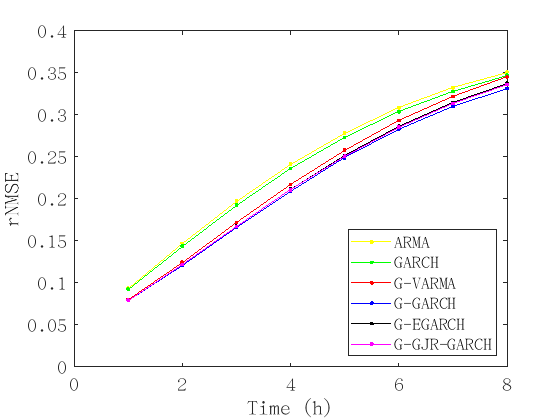

plot(t1,avg_rNMSE_H_ARMA(1:H1,1),'.-y')
hold on;
plot(t1,avg_rNMSE_H_GARCH(1:H1,1),'.-g')
hold on;
plot(t1,avg_rNMSE_H_GVARMA(1:H1,1),'.-r')
hold on;
plot(t1,avg_rNMSE_H_G_GARCH(1:H1,1),'.-b')
plot(t1,avg_rNMSE_H_G_EGARCH(1:H1,1),'.-k')
plot(t1,avg_rNMSE_H_G_GJR_GARCH(1:H1,1),'.-m')
xlabel('Time (h)'); ylabel('rNMSE')
legend({'ARMA','GARCH','G-VARMA','G-GARCH','G-EGARCH','G-GJR-GARCH'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 0.4])
xlim([0 8])

%savefig('stock-rNMSE-garch11.fig');

%%%%%%%%%5
figure
t1 = 1:H1
plot(t1,avg_MAE_H_ARMA(1:H1,1),'.-y')
hold on;
plot(t1,avg_MAE_H_GARCH(1:H1,1),'.-g')
plot(t1,avg_MAE_H_GVARMA(1:H1,1),'.-r')
hold on;
plot(t1,avg_MAE_H_G_GARCH(1:H1,1),'.-b')
hold on;
plot(t1,avg_MAE_H_G_EGARCH(1:H1,1),'.-k')
plot(t1,avg_MAE_H_G_GJR_GARCH(1:H1,1),'.-m')
xlabel('Time (h)'); ylabel('MAE (℃)')
legend({'ARMA','GARCH','G-VARMA','G-GARCH','G-EGARCH','G-GJR-GARCH'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 2.5])
xlim([0 8])
%savefig('stock-MAE-garch11.fig');

area = test_L
c_node = 4
g = figure()
t1 = 1:area
plot(t1,X_te(c_node,1:area))
hold on;
plot(t1,Pre_G_GARCH(c_node,1:area,3))
hold on;
plot(t1,Pre_GVARMA(c_node,1:area,3))
plot(t1,Pre_G_EGARCH(c_node,1:area,3))
plot(t1,Pre_G_GJR_GARCH(c_node,1:area,3))
xlabel('Time (h)'); ylabel('Temperature (℃)')
legend({'True signal','G-GARCH, 3 steps','G-VARMA, 3 steps','G-EGARCH, 3 steps','G-GJR-GARCH, 3 steps'},'Location','southeast')
set(gca,'FontSize',15)
set(gca,'FontSize',15)
%ylim([0 3.6])
%savefig('stock-pre3-node1-garch11.fig');

area = test_L

area = 372

c_node = 3

c_node = 3

HH = 3

HH = 3

g = figure()

g =   Figure (3) - 属性:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 1:area

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


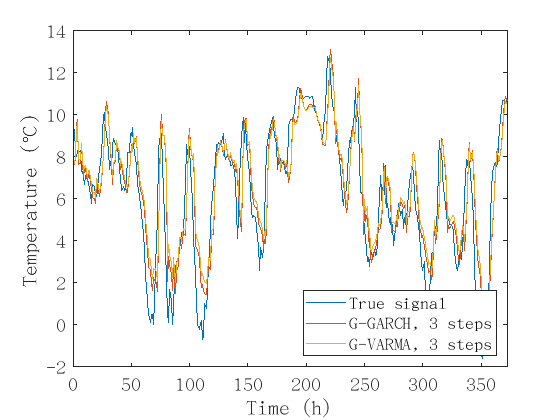

plot(t1,X_te(c_node,1:area))
hold on;
plot(t1,Pre_G_GARCH(c_node,1:area,HH))
hold on;
plot(t1,Pre_GVARMA(c_node,1:area,HH))
%plot(t1,Pre_G_EGARCH(c_node,1:area,3))
%plot(t1,Pre_G_GJR_GARCH(c_node,1:area,3))
xlabel('Time (h)'); ylabel('Temperature (℃)')
legend({'True signal','G-GARCH, 3 steps','G-VARMA, 3 steps'},'Location','southeast')
set(gca,'FontSize',15)
set(gca,'FontSize',15)
xlim([0 test_L])

%ylim([0 3.6])
%savefig('stock-pre3-node1-garch11.fig');

%%%% DIFFERENCE ERROR 
error_dis = error_GVARMA - error_G_GARCH

error_dis = error_dis(:,:,1) =

    0.0219   -0.0139   -0.0953    0.0531   -0.0170    0.1014    0.0571   -0.0779    0.0211    0.0776    0.0090    0.0547   -0.0745    0.0810   -0.1025   -0.0823    0.0902   -0.0419   -0.0364    0.0716    0.0910    0.0649   -0.0209   -0.0029    0.0167   -0.0387    0.0465   -0.0112    0.0400    0.0805    0.0999    0.1043   -0.0750    0.0256    0.0005   -0.0194   -0.0029    0.0272   -0.0674    0.0106    0.0861   -0.0847   -0.1130   -0.0862   -0.0874   -0.0023    0.0157   -0.0298   -0.0017   -0.0248   -0.0575   -0.0157    0.1062    0.0895   -0.0512   -0.1101    0.0881   -0.1015    0.1136   -0.0472   -0.1246    0.0875   -0.0712    0.1169    0.1629   -0.1524   -0.1151   -0.1205   -0.0748   -0.1612   -0.0325   -0.0271    0.0527    0.0939   -0.0037    0.0710    0.0724    0.0730   -0.2703   -0.1631   -0.1052    0.1643   -0.0249    0.1354   -0.1268   -0.1200    0.1061   -0.0717   -0.0508   -0.0718    0.0697   -0.0420   -0.0403   -0.0430   -0.0260    0.0370   -0.10

HH = 3

HH = 3

area = test_L

area = 372

c_node = 3

c_node = 3

line_1 = zeros(1,test_L)

line_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


g = figure()

g =   Figure (3) - 属性:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 1:area

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


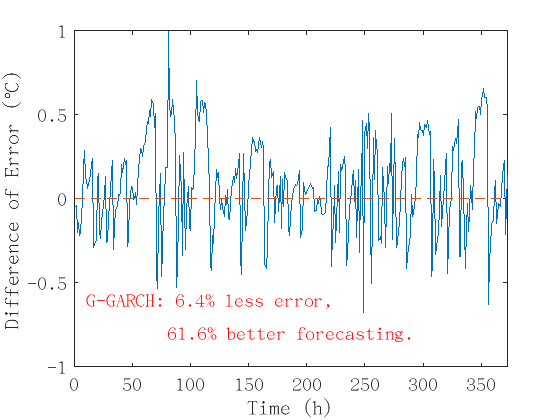

plot(t1,error_dis(c_node,1:area,HH))
hold on;
plot(t1,line_1(1,t1),'--')
xlabel('Time (h)'); ylabel('Difference of Error (℃)')
xlim([0 test_L])
ylim([-1 1])
text(10,-0.6,'G-GARCH: 6.4% less error,','Color','red','FontSize',15)
text(80,-0.8,'61.6% better forecasting.','Color','red','FontSize',15)
set(gca,'FontSize',15)




count = 0

count = 0

for i = 1:area
    if error_dis(c_node,i,HH) > 0
        count = count + 1;
    end
end

count/test_L

ans = 0.6156


error_1 = sum(error_GVARMA(c_node,1:area,HH));
error_2 = sum(error_G_GARCH(c_node,1:area,HH));
error_2/error_1

ans = 0.9357

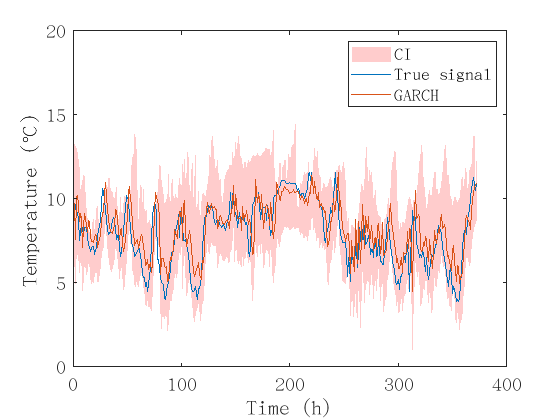

%save('Molene-12nodes-garch11')
%load('Molene-12nodes-garch11')
%save('Molene-12nodes-garch11-with-CI')
%load('Molene-12nodes-garch11-with-CI')

%%%% plot confidence interval of G-GARCH

area = test_L

area = 372

c_node = 3

c_node = 3

g = figure()

g =   Figure (2) - 属性:

      Number: 2
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 1:area

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


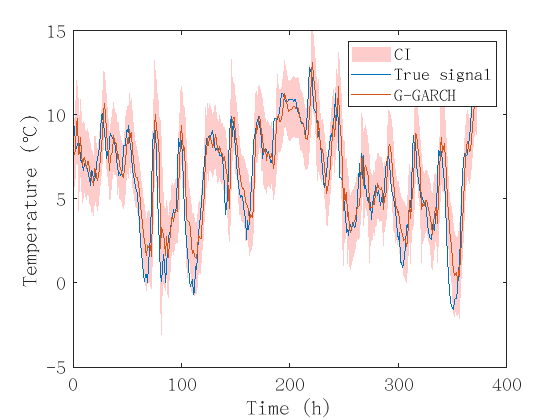

t1conf = [t1 t1(end:-1:1)];
y_low = Pre_G_GARCH_low(c_node,1:area,3);
y_high = Pre_G_GARCH_high(c_node,1:area,3);
y_G_GARCH_conf = [y_low y_high(end:-1:1)];
p_ggarch = fill(t1conf,y_G_GARCH_conf,'red');
p_ggarch.FaceColor = [1 0.8 0.8];%定义区间的填充颜色      
p_ggarch.EdgeColor = 'none';%定义区间边界的填充颜色，此处不设置
hold on
plot(t1,X_te(c_node,1:area))
hold on;
plot(t1,Pre_G_GARCH(c_node,1:area,3))
hold on;
xlabel('Time (h)'); ylabel('Temperature (℃)')
legend({'CI','True signal','G-GARCH'},'Location','northeast')
set(gca,'FontSize',15)
set(gca,'FontSize',15)
hold off
%ylim([0 3.6])
ylim([-5 15])

area = test_L

area = 372

c_node = 3

c_node = 3

g = figure()

g =   Figure (3) - 属性:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [232 246 560 420]
       Units: 'pixels'

  显示 所有属性


t1 = 1:area

t1 =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


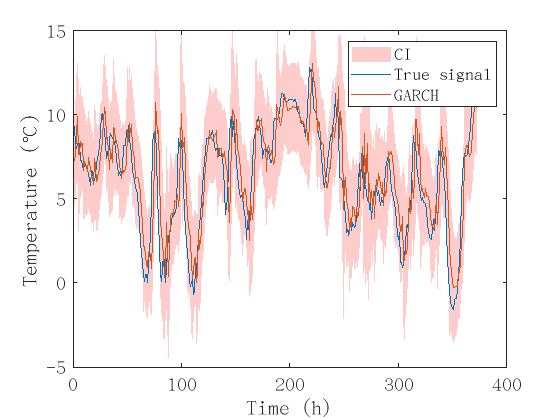

t1conf = [t1 t1(end:-1:1)];
y_low = Pre_GARCH_low(c_node,1:area,3);
y_high = Pre_GARCH_high(c_node,1:area,3);
y_GARCH_conf = [y_low y_high(end:-1:1)];
p_ggarch = fill(t1conf,y_GARCH_conf,'red');
p_ggarch.FaceColor = [1 0.8 0.8];%定义区间的填充颜色      
p_ggarch.EdgeColor = 'none';%定义区间边界的填充颜色，此处不设置
hold on
plot(t1,X_te(c_node,1:area))
hold on;
plot(t1,Pre_GARCH(c_node,1:area,3))
xlabel('Time (h)'); ylabel('Temperature (℃)')
legend({'CI','True signal','GARCH'},'Location','northeast')
set(gca,'FontSize',15)
set(gca,'FontSize',15)
hold off
ylim([-5 15])

line_arma_mae   = avg_MAE_H_ARMA(3,1)

line_arma_mae = 1.1200

line_arma_rnmse = avg_rNMSE_H_ARMA(3,1)

line_arma_rnmse = 0.1975

line_garch_mae   = avg_MAE_H_GARCH(3,1)

line_garch_mae = 1.0734

line_garch_rnmse = avg_rNMSE_H_GARCH(3,1)

line_garch_rnmse = 0.1926

line_gvarma_mae =  avg_MAE_H_GVARMA(3,1)

line_gvarma_mae = 0.9530

line_gvarma_rnmse =avg_rNMSE_H_GVARMA(3,1)

line_gvarma_rnmse = 0.1720


% principal component
Pre_G_GARCH_hpf = zeros(N,test_L,N);
diag_list = zeros(1,N)

diag_list =      0     0     0     0     0     0     0     0     0     0     0     0


error_GARCH_hpf = zeros(N,test_L,N);
MAE_H_GARCH_hpf = zeros(N,N);
avg_MAE_H_GARCH_hpf = zeros(N,1);
rNMSE_H_GARCH_hpf = zeros(N,N);
avg_rNMSE_H_GARCH_hpf = zeros(N,1);

for h_pass = 1:N
    diag_list(1,h_pass) = 1
    Pre_G_GARCH_hpf(:,:,h_pass) = V*diag(diag_list,0)*prediction(:,:,3);
    
    error_G_GARCH_hpf(:,:,h_pass) = abs(Pre_G_GARCH_hpf(:,:,h_pass) - X_te(:,:));
    MAE_H_G_GARCH_hpf(:,h_pass)  = sum(error_G_GARCH_hpf(:,:,h_pass),2)/(test_L);
    avg_MAE_H_G_GARCH_hpf(h_pass,1) = sum(MAE_H_G_GARCH_hpf(:,h_pass))/N;
    rNMSE_H_G_GARCH_hpf(:,h_pass) = sqrt(sum(error_G_GARCH_hpf(:,:,h_pass).^2,2)./sum(X_te(:,:).^2,2));
    avg_rNMSE_H_G_GARCH_hpf(h_pass,1) = sqrt(sum(sum(error_G_GARCH_hpf(:,:,h_pass).^2,2))/sum(sum(X_te(:,:).^2,2)));

end

diag_list =      1     0     0     0     0     0     0     0     0     0     0     0


diag_list =      1     1     0     0     0     0     0     0     0     0     0     0


diag_list =      1     1     1     0     0     0     0     0     0     0     0     0


diag_list =      1     1     1     1     0     0     0     0     0     0     0     0


diag_list =      1     1     1     1     1     0     0     0     0     0     0     0


diag_list =      1     1     1     1     1     1     0     0     0     0     0     0


diag_list =      1     1     1     1     1     1     1     0     0     0     0     0


diag_list =      1     1     1     1     1     1     1     1     0     0     0     0


diag_list =      1     1     1     1     1     1     1     1     1     0     0     0


diag_list =      1     1     1     1     1     1     1     1     1     1     0     0


diag_list =      1     1     1     1     1     1     1     1     1     1     1     0


diag_list =      1     1     1     1     1     1     1     1     1     1     1     1


%%%%%%%%%5
figure
hpf = 1:N

hpf =      1     2     3     4     5     6     7     8     9    10    11    12


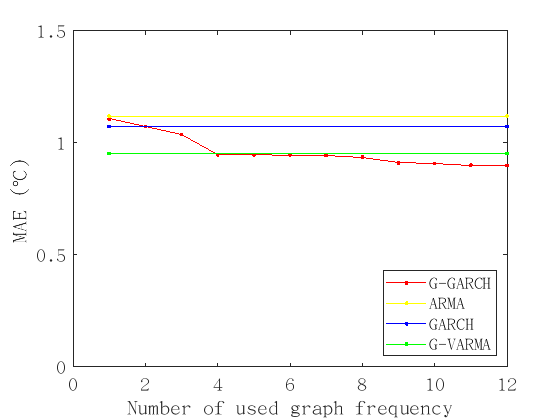

plot(hpf,avg_MAE_H_G_GARCH_hpf(hpf,1),'.-r')
hold on;
plot([1,12],[line_arma_mae,line_arma_mae],'.-y')
plot([1,12],[line_garch_mae,line_garch_mae],'.-b')
plot([1,12],[line_gvarma_mae,line_gvarma_mae],'.-g')
%plot(hpf,avg_rNMSE_H_G_GARCH_hpf(h_pass,1),'.-g')
xlabel('Number of used graph frequency'); ylabel('MAE (℃)')
legend({'G-GARCH','ARMA','GARCH','G-VARMA'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 1.5])

%xlim([0 8])

%%%%%%%%%5
figure
hpf = 1:N

hpf =      1     2     3     4     5     6     7     8     9    10    11    12


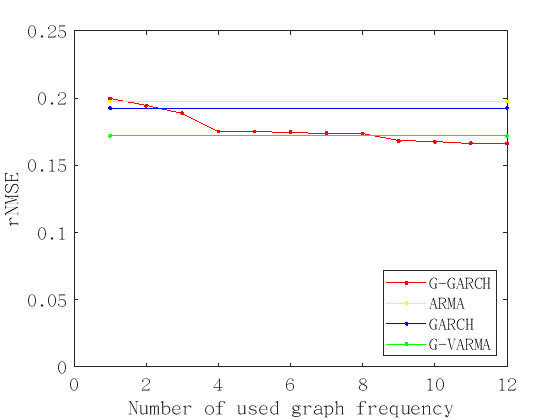

plot(hpf,avg_rNMSE_H_G_GARCH_hpf(hpf,1),'.-r')
hold on;
plot([1,12],[line_arma_rnmse,line_arma_rnmse],'.-y')
plot([1,12],[line_garch_rnmse,line_garch_rnmse],'.-b')
plot([1,12],[line_gvarma_rnmse,line_gvarma_rnmse],'.-g')
xlabel('Number of used graph frequency'); ylabel('rNMSE')
legend({'G-GARCH','ARMA','GARCH','G-VARMA'},'Location','southeast')
set(gca,'FontSize',15)
ylim([0 0.25])

%xlim([0 8])

[V,test1] = forecast(EstMdl,j,'Y0',Xhat(i,1:index_in -j +index)')

node1 = 12
h1 = 3
E1 = max(error_G_EGARCH(node1,:,h1))
G1 = max(error_G_GARCH(node1,:,h1))
V1 = max(error_GVARMA(node1,:,h1))
GJR1 = max(error_G_GJR_GARCH(node1,:,h1))
G2  = max(error_GARCH(node1,:,h1))
A1 = max(error_ARMA(node1,:,h1))

for i = 1:N
    Mdl = arima(3,0,0);
    EstMdl = estimate(Mdl,X(i,1:744)');
    [res,~,logL] = infer(EstMdl,X(i,1:744)');
    [h,pValue,stat,cValue] = archtest(res)
    figure
    plot(res.*res)
end

H = zeros(N,1)
PVALUE = zeros(N,1)
STAT = zeros(N,1)
CVALUE = zeros(N,1)
for i = 1:N
    Mdl = arima(3,0,0);
    EstMdl = estimate(Mdl,Xhat(i,1:744)');
    [res,~,logL] = infer(EstMdl,Xhat(i,1:744)');
    [H(i,1),PVALUE(i,1),STAT(i,1),CVALUE(i,1)] = archtest(res)
    %figure
    %plot(res.*res)
end

H = zeros(N,1)
PVALUE = zeros(N,1)
STAT = zeros(N,1)
CVALUE = zeros(N,1)
for i = 1:N
    Mdl = arima(3,0,0);
    EstMdl = estimate(Mdl,X(i,1:744)');
    [res,~,logL] = infer(EstMdl,X(i,1:744)');
    [H(i,1),PVALUE(i,1),STAT(i,1),CVALUE(i,1)] = archtest(res)
    %figure
    %plot(res.*res)
end

for i = 1:N
    Mdl = arima(3,0,0);
    EstMdl = estimate(Mdl,Xhat(i,1:744)');
    [res,~,logL] = infer(EstMdl,Xhat(i,1:744)');
    [h,pValue,stat,cValue] = archtest(res)
    figure
    plot(res.*res)
end

%%%%%%%%% Using the Laplacian matrix with distance
%Ldis_name = 'L_distance'
%L_dis = load(fullfile(path_data,strcat(Ldis_name,'.mat'))).name(:,:)
%%%%%%%%% Using the Laplacian matrix with corr
%Ldis_name = 'L_corr'
%L_corr = load(fullfile(path_data,strcat(Ldis_name,'.mat'))).name(:,:)
